# Excersise 5

import plotFrame.*;

clear all;
clc;

l01 = 2;
l12 = 2;
l23 = 2;
l3W = 2;
lWE = 2;

PE = [4 4 4]';

theta = pi/4; % angle from horiDzontal axis
phi = pi/4; % angle from vertical axis

phi1 = pi/4;
phi2 = pi/8;
phi3 = pi/8;
phi4 = 0;
phi5 = -pi/4;
phi6 = 0;

H10 = DHMatrix(0, 0, l01, phi1);
H21 = DHMatrix(l12, pi/2, 0, phi2);
H32 = DHMatrix(l23, 0, 0, phi3);
H43 = DHMatrix(0, -pi/2, l3W, phi4);
H54 = DHMatrix(0, pi/2, 0, phi5);
H65 = DHMatrix(0, 0, lWE, phi6);

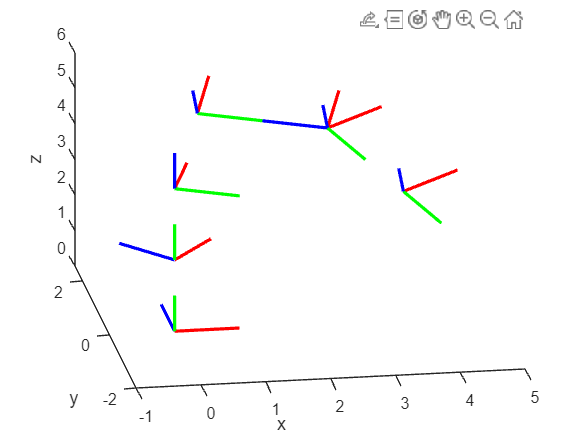

% plotting the reference frames
clf;
hold on;

plotFrame(eye(4));
plotFrame(H10);
plotFrame(H10*H21);
plotFrame(H10*H21*H32);
plotFrame(H10*H21*H32*H43);
plotFrame(H10*H21*H32*H43*H54);
plotFrame(H10*H21*H32*H43*H54*H65);
view([-9 30]);
xlabel('x');
ylabel('y');
zlabel('z');

function matrix = DHMatrix(a, alpha, d, theta)
     % function to create the matrix from the DH table row
    matrix = [ cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);
               sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
               0 sin(alpha) cos(alpha) d;
               0 0 0 1
             ];
end